
Phi=0:89; %phi=90 would give a non-real number
g=9.81;
H=644.80/1000; % grasp release height
x=208/1000;
z0=0; %level ground impact

X=zeros;
Y=zeros;
VX=zeros;
VY=zeros;
x_0=0; %initial pos x
y_0=0; %initial pos y
v_0=20; % m/s
%v_0=min(v_0(v_0~=0)); % m/s

g=9.81; 
phi_zero=deg2rad(13)

phi_zero = 0.2269

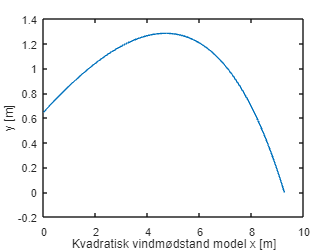

%phi_zero=deg2rad(find(v_0==v_0_num));
radius=0.02;
C_d=0.4; %for spherical object 
rho=1.293;
A=pi*radius^2;
m=0.0027;
h=-0.1*pi/180; %step size of -0.1 degrees
v_x0=v_0*cos(phi_zero);
v_y0=v_0*sin(phi_zero);
b=0.5*C_d*rho*A;
v_t=sqrt((m*g)/b); %terminal velocity     
%initial values 
X(1)=0;
Y(1)=H;
VX(1)=v_x0;
VY(1)=v_y0;
n=1;
%while abs(y1-Y(n))<0.001 & abs(y1-Y(n))>0
while Y(n)>=0
    n=n+1;
    phi=phi_zero+h*(n-1);
    v_x=v_x0/sqrt(1+(v_x0/v_t)^2*((tan(phi_zero)/cos(phi_zero))-(tan(phi)/cos(phi))+log(abs(sec(phi_zero)+tan(phi_zero))/abs(sec(phi)+tan(phi)))));
    v_y=v_x*tan(phi); %needs to be expanded to also have rk4 implementation. 

    vk1x=sec(phi)*v_x; %equation for v used to find k1 for x 
    xk_1=-(1/g)*vk1x^2*h;

    vk2x=sec(phi+h/2)*v_x;
    xk_2=-(1/g)*vk2x^2*h;

    vk3x=sec(phi+h/2)*v_x;
    xk_3=-(1/g)*vk3x^2*h;

    vk4x=sec(phi+h)*v_x;
    xk_4=-(1/g)*vk4x^2*h;

    x=X(n-1)+(xk_1+2*xk_2+2*xk_3+xk_4)/6;
    X(n)=x;
    VX(n)=v_x; %needs rk4 method as well by incrementing the phi values. 

    %vk1x...vk4x can be can be reused as the same general velocity formula also applies
    %for y. 
    yk_1=-(1/g)*vk1x^2*tan(phi)*h;
    yk_2=-(1/g)*vk2x^2*tan(phi+h/2)*h;
    yk_3=-(1/g)*vk3x^2*tan(phi+h/2)*h;
    yk_4=-(1/g)*vk4x^2*tan(phi+h)*h;
    y=Y(n-1)+(yk_1+2*yk_2+2*yk_3+yk_4)/6;
    Y(n)=y;
    VY(n)=v_y;

    %if the stop point is reached, stop the robot. 
end 
% if((y1-Y(n))>0.001)
% phi_zero=phi_zero+0.1;
% end 
% if((y1-Y(n))<-0.001)
% phi_zero=phi_zero-0.1;
% end
% end

  %xlim([0 1]);
  %ylim([0 1]);
% xlabel("x [m]");
% ylabel("y [m]");
x=X(n);
y=Y(n);
%end

%tges=(2*(v_0.*sin(phi_zero)+H/tges))/g; %time when z=0
tges=(-v_0*sin(phi_zero)-sqrt(v_0^2*sin(phi_zero)^2+2*g*H))/-g;
t =linspace(0,tges);
x=v_0*t*cos(phi_zero)+x_0;
z=-1/2*g.*t.^2+v_0.*t.*sin(phi_zero)+H;
figure;
plot(X,Y);

xlabel("Kvadratisk vindmødstand model x [m]");
ylabel("y [m]");

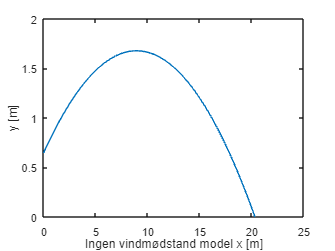

figure;
plot(x,z);

xlabel("Ingen vindmødstand model x [m]");
ylabel("y [m]");